# `SYSID - Atividade 06`

`Aluno: Pedro Henrique Cardoso Paulo`

`Professor: Helon`

## Passo 0 - Limpando prompt e carregando dados


clc 
clear 
close all

addpath(genpath('Contsid'))

% time R2 R3 An2 An3 DC_Torque
rawData = dlmread('measured_data.csv');

% plot(rawData(:,1),rawData(:,5))
% plot(diff(rawData(:,1)))

## Passo 1 - Visualizando timesteps

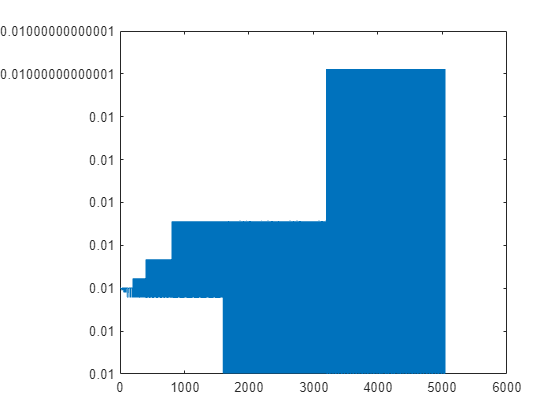


Ts = 1e-2;
fs = 1/Ts;
[resData, t] = resample(rawData(:,2:end),rawData(:,1),fs);

plot(diff(t))

## Passo 3 - Visualizando os valores

### 3.1 - Sem aplicação de filtro

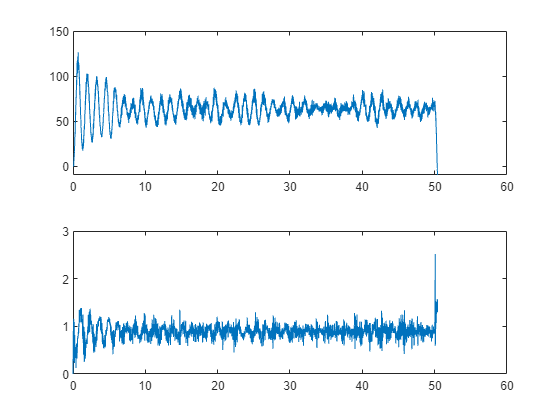

y = resData(:,1);
u = resData(:,5);
figure
subplot(2,1,1)
plot(t,y)
subplot(2,1,2)
plot(t,u)

### 3.2 - Aplicando filtro

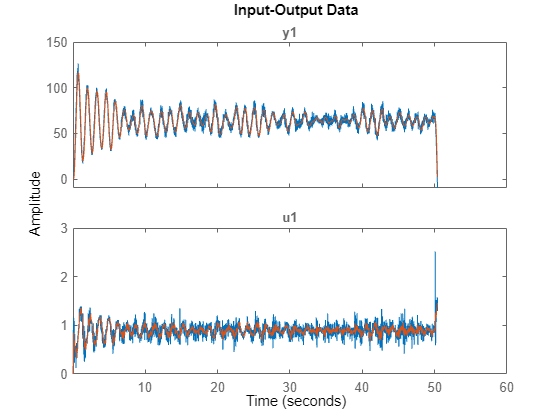

z = iddata(y,u,Ts);
[B,A] = butter(2,1e-1);
zf = idfilt(z,{B,A});

figure
plot(z,zf)

## Passo 4 - Estimando o modelo com Contsid

### 4.1 - Estimando o modelo

% estimate model using CONTSID
np = 5;
nz = 1;
Ghat = tfrivc(z,np,nz,'TdMax',0);

### 4.2 - Analisando o espectro da solução

pole(Ghat)

ans =  -10.0348 + 0.0000i
  -0.6593 + 5.1970i
  -0.6593 - 5.1970i
  -1.7427 + 1.7194i
  -1.7427 - 1.7194i


zero(Ghat)

ans = 2.0783

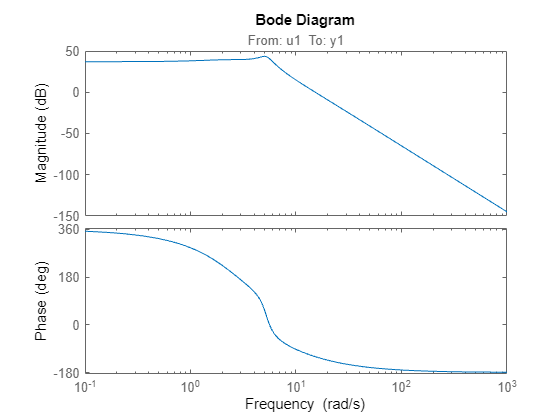

bode(Ghat)

### 4.3 - Simulando o resultado

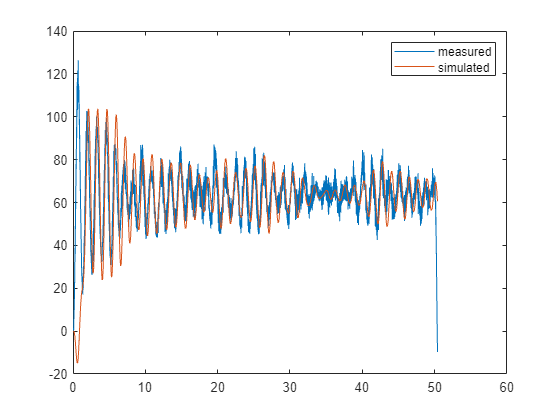

% model output comparison
ye = lsim(Ghat,u,t);
figure
plot(t,[y,ye]);
legend('measured','simulated')

### 4.4 - Comparando os resultados

% Metrica R2
R2_COMP = mult_corr(y,ye)

R2_COMP = -0.5569

## Passo 5 - Conclusões

- Os resultados obtidos pelo uso da Contsid foram visualmente satisfatórios

- A secomparar os erros em nível de R2, a mérica apresentou valores runis. Porém, o resultado visualmente pareceu representar a física do problema

- Os polos indicam frequências naturais baixas. Provavelmente o uso de maiores tempos de aquisição, com a possibilidade de capturarmos dinâmicas mais lentas, trariam mais ganhos para o problema